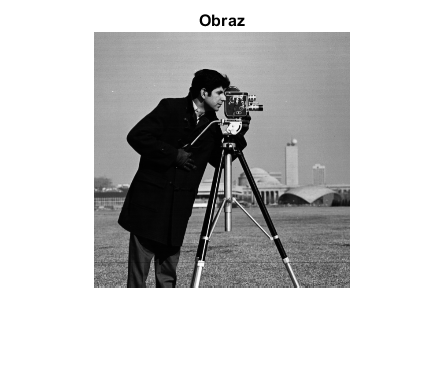

clear all; close all;
% Inicjalizacja − wczytaj obraz
[x,cmap] = imread('cameraman.tif'); % wczytaj obraz do "x" i jego paletę kolorów do "cmap"
imshow(x,cmap), title('Obraz'); pause % pokaż obraz wykorzystując jego paletę

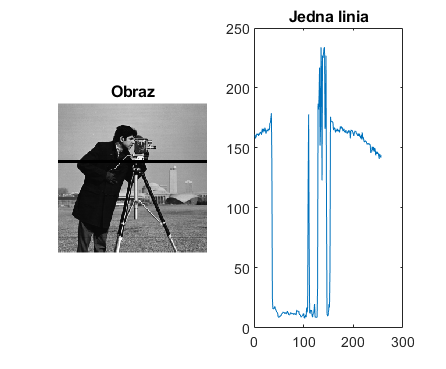

[M, N] = size(x); % odczytaj liczbę wierszy i kolumn; założenie M=N !!!
x = double(x); % zamień reprezentację pikseli
% Macierz transformacji 1D DCT oraz 1D DFT
n=0:N-1; % numery próbek funkcji bazowych
c = [sqrt(1/N) sqrt(2/N)*ones(1,N-1)]; f = 1/sqrt(N); % współczynniki normalizujące
for k=0:N-1 % wyznacz macierz transformacji
C(k+1,n+1) = c(k+1) * cos( pi*k*(n+1/2) / N ); % funkcje bazowe 1D DCT
F(k+1,n+1) = f * exp(j*2*pi/N*k*n); % funkcje bazowe 1D DFT
end
% JEDNA LINIA
Nr = 100; K = 2; y = x; % numer linii, szerokość znacznika, kopia obrazu
linia = x(Nr,1:N); % pobranie linii
y(Nr-K:Nr+K,1:N) = 0*ones(2*K+1,N); % zaznacz wybraną linię czarnym kolorem
subplot(121); imshow(y,cmap); title('Obraz'); % pokaż obraz z czarną linią
subplot(122); plot(linia); title('Jedna linia'); pause % pokaż wykres linii obrazu

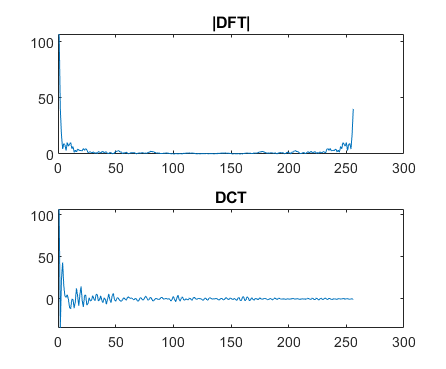

subplot(211); plot( abs(fft(linia))/N ); title('|DFT|'); % DFT linii obrazu
% subplot(212); plot( dct(linia)/sqrt(N) ); title('DCT'); pause % DCT (Matlab) linii
subplot(212); plot( (conj(C)*linia')/sqrt(N) ); title('DCT'); pause % DCT (nasze) linii

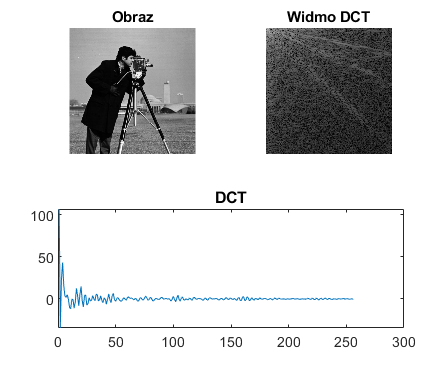

% FILTRACJA za pomocą 2D DCT
K = 64; H = zeros(M,N); H(1:K,1:K) = ones(K,K); % maska częstotliwościowa, lewy górny róg
 X = dct2(x); % 2D DCT − MATLABA
%X = conj(C) * x * conj(C).'; % 2D DCT − NASZE (dla DCT conj(C)=C)
Y = X .* H; % iloczyn widma DCT i maski
% y = idct2(Y); % 2D IDCT − MATLABA
y = C.' * Y * C; % 2D IDCT − NASZE
XdB = skaladB( X ); YdB = skaladB( Y ); % wyskalowanie intensywności pikseli w dB
subplot(221); imshow(x, cmap); title('Obraz'); % dalej tylko wizualizacja
subplot(222); imshow(XdB, cmap); title('Widmo DCT');

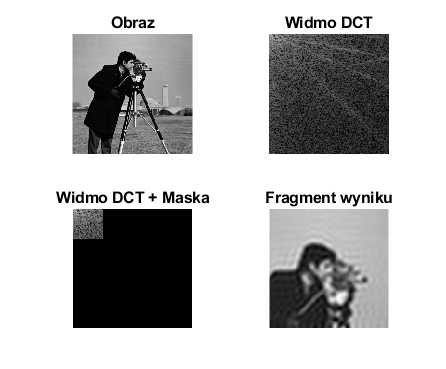

subplot(223); imshow(YdB, cmap); title('Widmo DCT + Maska');
subplot(224); imshow(y(1:128,65:192), cmap); title('Fragment wyniku'); pause

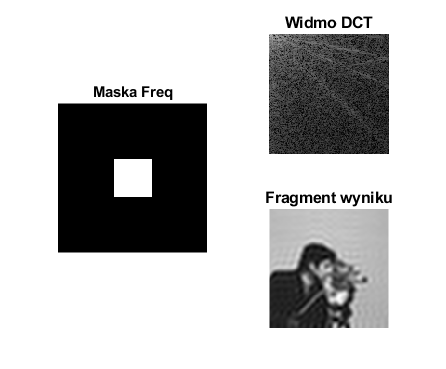

% FILTRACJA 2D za pomocą 2D DFT (fftshift2D - przestawianie ćwiartek widma 2D DFT, patrz rys. 22.11a)
K = 32; H = zeros(M,N); % maska częstotliwościowa H (MxN)
H(M/2+1-K : M/2+1+K, N/2+1-K : N/2+1+K) = ones(2*K+1,2*K+1); % środek = (M/2+1, N/2+1)
h = fftshift2D( real( ifft2( fftshift2D(H) ) ) ); % jej odpowiedź impulsowa
subplot(121); imshow(255*H,cmap); title('Maska Freq'); % rysunek maski

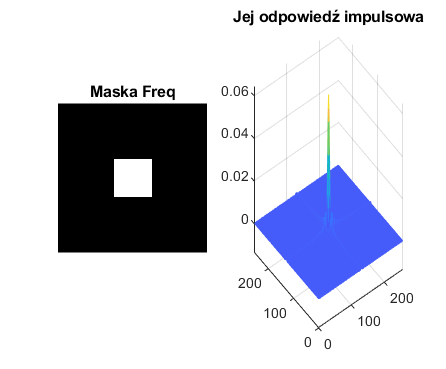

subplot(122); mesh(h); title('Jej odpowiedź impulsowa'); pause % rysunek jej odp. impulsowej

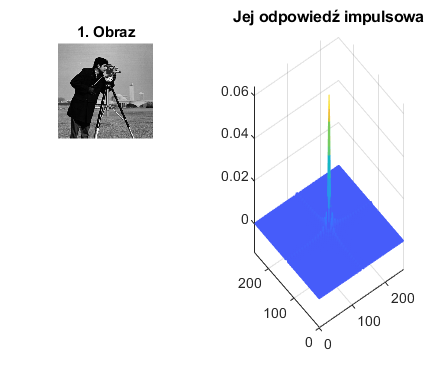

% X = fft2(x)/N; % transformacja Fouriera 2D DFT − MATLABA
X = conj(F) * x * conj(F).'; % transformacja Fouriera 2D DFT − NASZA
Xp = fftshift2D(X); % przestawienie miejscami ćwiartek widma
Yp = Xp .* H; % filtracja = iloczyn widma 2D DFT i maski 2D
Y = fftshift2D(Yp); % powrotne przestawienie ćwiartek widma
% y1 = ifft2(Y)*N; % odwrotna transformacja Fouriera 2D IDFT − MATLABA
y1 = F.' * Y * F; % odwrotna transformacja Fouriera 2D IDFT − NASZA
y1 = real(y1); % część rzeczywista, urojona równa zeru
y1f = y1(1:128,65:192); % wybranie fragmentu obrazu do wizualizacji
YdB = skaladB( Y ); YpdB = skaladB( Yp );
subplot(231); imshow(x, cmap); title('1. Obraz');

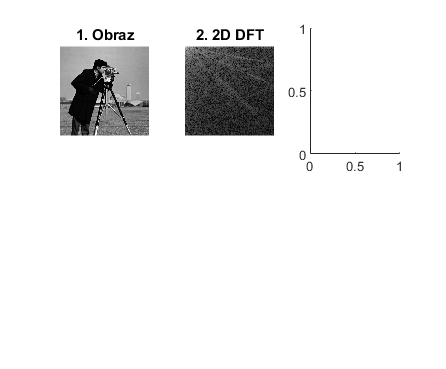

Unrecognized function or variable 'XpdB'.

subplot(232); imshow(XdB, cmap); title('2. 2D DFT');
subplot(233); imshow(XpdB, cmap); title('3. Po przestawieniu');

subplot(234); imshow(YpdB, cmap); title('4. Po filtrze');
subplot(235); imshow(YdB, cmap); title('5. Po przestawieniu');
subplot(236); imshow(y1f, cmap); title('6. Fragment wyniku'); pause
% FILTRACJA 2D za pomocą splotu 2D
L = 32; y2 = conv2(x, h(M/2+1-L:M/2+1+L, N/2+1-L:N/2+1+L),'same');
subplot(121); imshow(y1,cmap); title('Obraz po filtrze FREQ - splot cykliczny');
subplot(122); imshow(y2,cmap); title('Obraz po filtrze CONV - splot liniowy'); pause